n=200;
sigma = 1;
K=2;
rounding = 1e-4;
cluster_true = [repelem(1,n/2), repelem(-1,n/2)];
n_iter = 10; 
%%%%%%%%%%%%
sep = 4;
%%%%%%%%%%%%%
s = 10;
M = sqrt(sep^2 / 4 / s);
rng(15)

p=5000

p = 5000

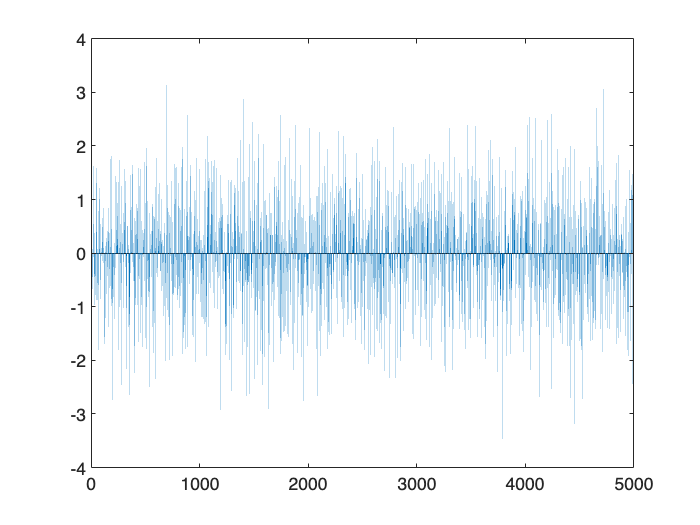

sparse_mean = [repelem(1,s), repelem(0,p-s)];
mu_1 =  -M * sparse_mean;
mu_2 =   M * sparse_mean;
mu_1_mat = repmat(mu_1, n/2,1);
mu_2_mat = repmat(mu_2, n/2,1);
    
        
x_noiseless = [ mu_1_mat ; mu_2_mat ];

e=eig(x_noiseless*x_noiseless');
e_sorted = -sort(-e);



x_noisy = [ mu_1_mat ; mu_2_mat ] + sigma^2 * randn(n, p);
bar(x_noisy(2,:))

[V,D] = eig(x_noisy * x_noisy');
[d,ind] = sort(diag(D), "descend");
Ds = D(ind,ind);
Vs = V(:,ind);
eigenval_vec = diag(D,0)

eigenval_vec = 1.0e+03 *

    3.2435
    3.2753
    3.3228
    3.3507
    3.3640
    3.3793
    3.4073
    3.4507
    3.4588
    3.4665


eigenval_vec_sorted= -sort(-eigenval_vec)

eigenval_vec_sorted = 1.0e+03 *

    7.1283
    7.0456
    7.0029
    6.9217
    6.9171
    6.8913
    6.8145
    6.8034
    6.7670
    6.7486


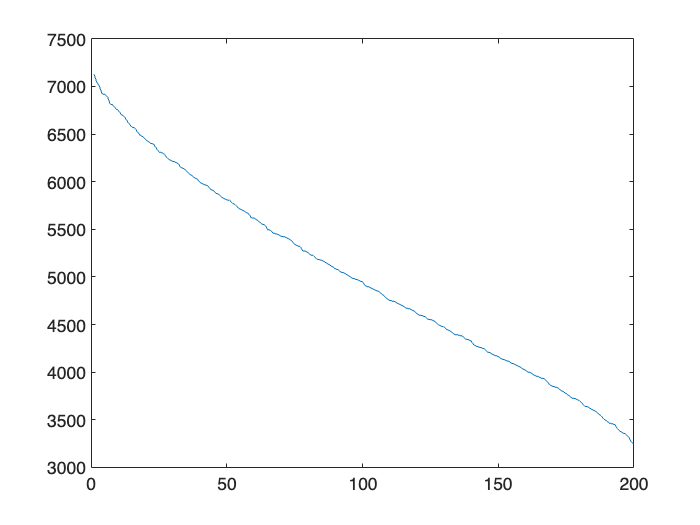

plot(eigenval_vec_sorted)

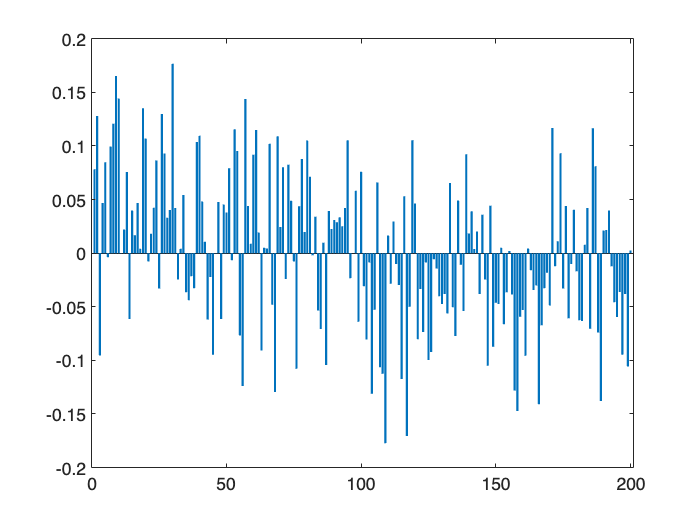

bar(Vs(:,1))

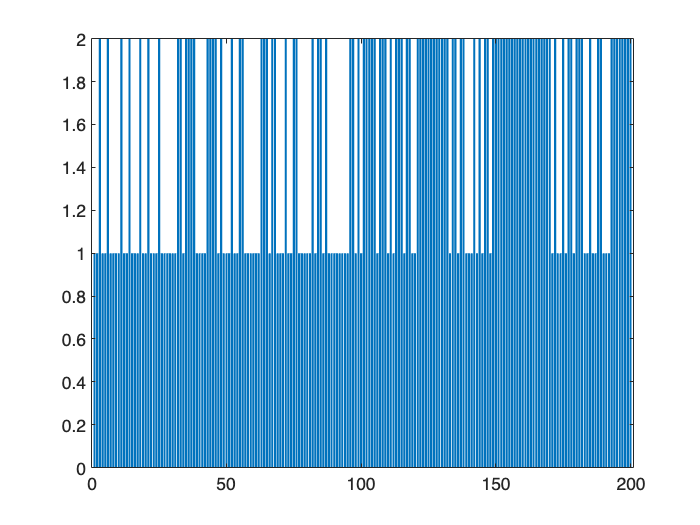

[idx,C] = kmeans(Vs(:,1),K);
bar(idx)

eigenval_vec = 1.0e+03 *

    1.6312
    1.7043
    1.7377
    1.7532
    1.7812
    1.7993
    1.8137
    1.8210
    1.8336
    1.8531


eigenval_vec_sorted = 1.0e+03 *

    5.0817
    4.6477
    4.6201
    4.5832
    4.5448
    4.5241
    4.4673
    4.4523
    4.4230
    4.3807